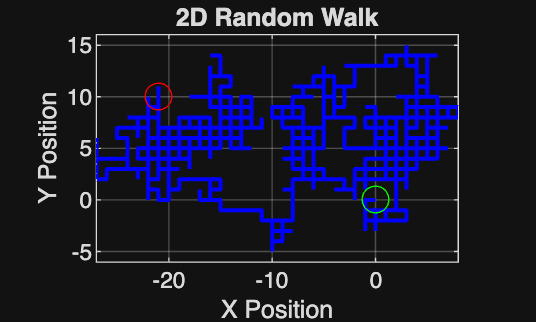

% Number of steps in the random walk
numSteps = 1000;

% Initialize position
x = zeros(numSteps, 1);
y = zeros(numSteps, 1);

% Simulate the random walk
for i = 2:numSteps
    % Randomly choose a direction: 1 = right, 2 = left, 3 = up, 4 = down
    direction = randi(4);
    switch direction
        case 1
            x(i) = x(i-1) + 1; % Move right
            y(i) = y(i-1);
        case 2
            x(i) = x(i-1) - 1; % Move left
            y(i) = y(i-1);
        case 3
            x(i) = x(i-1); % Move up
            y(i) = y(i-1) + 1;
        case 4
            x(i) = x(i-1); % Move down
            y(i) = y(i-1) - 1;
    end
end

% Create the plot
figure;
plot(x, y, 'b-', 'LineWidth', 1.5); % Plot the path
hold on;
plot(x(1), y(1), 'go', 'MarkerSize', 10); % Starting point
plot(x(end), y(end), 'ro', 'MarkerSize', 10); % Ending point
title('2D Random Walk');
xlabel('X Position');
ylabel('Y Position');
grid on;
axis equal; % Equal scaling for both axes
hold off;

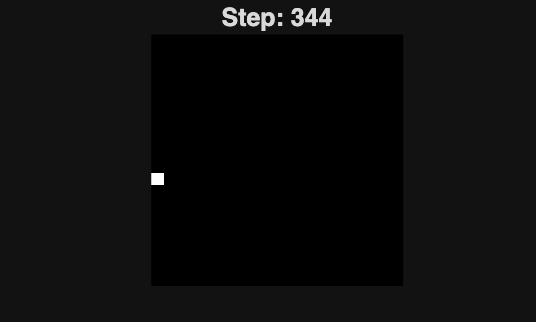

Index in position 2 is invalid. Array indices must be positive integers or logical values.

% Number of steps in the random walk
numSteps = 1000;

% Initialize position
x = zeros(numSteps, 1);
y = zeros(numSteps, 1);

% Create a figure for the images
figure;

% Simulate the random walk
for i = 2:numSteps
    % Randomly choose a direction: 1 = right, 2 = left, 3 = up, 4 = down
    direction = randi(4);
    switch direction
        case 1
            x(i) = x(i-1) + 1; % Move right
            y(i) = y(i-1);
        case 2
            x(i) = x(i-1) - 1; % Move left
            y(i) = y(i-1);
        case 3
            x(i) = x(i-1); % Move up
            y(i) = y(i-1) + 1;
        case 4
            x(i) = x(i-1); % Move down
            y(i) = y(i-1) - 1;
    end

    % Create a blank image
    img = zeros(20, 20); % Create a 20x20 image
    img(11 + y(i), 11 + x(i)) = 1; % Mark the current position

    % Display the image
    imshow(img, 'InitialMagnification', 'fit');
    title(['Step: ', num2str(i)]);
    pause(0.1); % Pause to visualize the movement
end

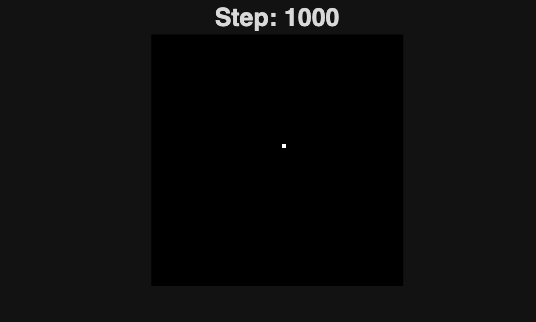

% Number of steps in the random walk
numSteps = 1000;

% Initialize position
x = zeros(numSteps, 1);
y = zeros(numSteps, 1);

% Create a figure for the images
figure;

% Simulate the random walk
for i = 2:numSteps
    % Randomly choose a direction: 1 = right, 2 = left, 3 = up, 4 = down
    direction = randi(4);

    % Check boundaries before moving
    switch direction
        case 1 % Move right
            if x(i-1) < 30 % Ensure within bounds
                x(i) = x(i-1) + 1;
                y(i) = y(i-1);
            else
                x(i) = x(i-1); % Stay in place
                y(i) = y(i-1);
            end
        case 2 % Move left
            if x(i-1) > -30 % Ensure within bounds
                x(i) = x(i-1) - 1;
                y(i) = y(i-1);
            else
                x(i) = x(i-1); % Stay in place
                y(i) = y(i-1);
            end
        case 3 % Move up
            if y(i-1) < 30 % Ensure within bounds
                x(i) = x(i-1);
                y(i) = y(i-1) + 1;
            else
                x(i) = x(i-1); % Stay in place
                y(i) = y(i-1);
            end
        case 4 % Move down
            if y(i-1) > -30 % Ensure within bounds
                x(i) = x(i-1);
                y(i) = y(i-1) - 1;
            else
                x(i) = x(i-1); % Stay in place
                y(i) = y(i-1);
            end
    end

    % Create a blank image
    img = zeros(60, 60); % Create a 20x20 image
    img(31 + x(i), 31 + y(i)) = 1; % Mark the current position

    % Display the image
    imshow(img, 'InitialMagnification', 'fit');
    title(['Step: ', num2str(i)]);
    pause(0.1); % Pause to visualize the movement
end

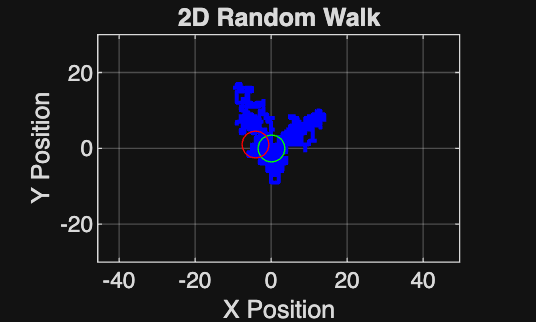


% Create the plot
figure;
plot(x, y, 'b-', 'LineWidth', 1.5); % Plot the path
hold on;
plot(x(1), y(1), 'go', 'MarkerSize', 10); % Starting point
plot(x(end), y(end), 'ro', 'MarkerSize', 10); % Ending point
title('2D Random Walk');
xlabel('X Position');
ylabel('Y Position');
xlim([-30,30])
ylim([-30,30])
grid on;
axis equal; % Equal scaling for both axes
hold off;